Código para analizar la imagen de la cámara y conseguir el nivel de altura del agua. 

La entrada es una imagen y la salida un número: el nivel de agua en metros.

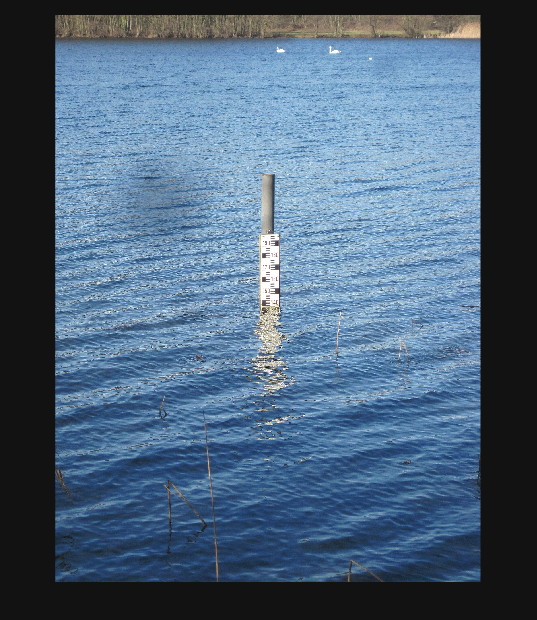

clear, close all

im = imread("ref06_m_blankensee_lago_olas.jpg");

figure
imshow(im);

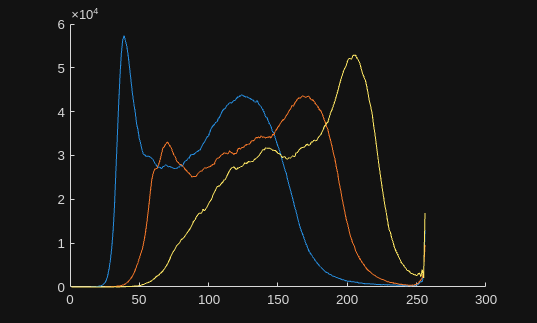


im_r = im(:,:,1);
im_g = im(:,:,2);
im_b = im(:,:,3);

hist_r = imhist(im_r);
hist_g = imhist(im_g);
hist_b = imhist(im_b);

figure
hold on 
plot(hist_r);
plot(hist_g);
plot(hist_b);
hold off

Gradiente de la imagen

% [Gmag, Gdir] = imgradient(im_g);
% imshow(Gmag);

Apertura

% se = strel('disk',2);
% Gmag_close = imclose(Gmag, se);
% imshow(Gmag_close);


Umbralización

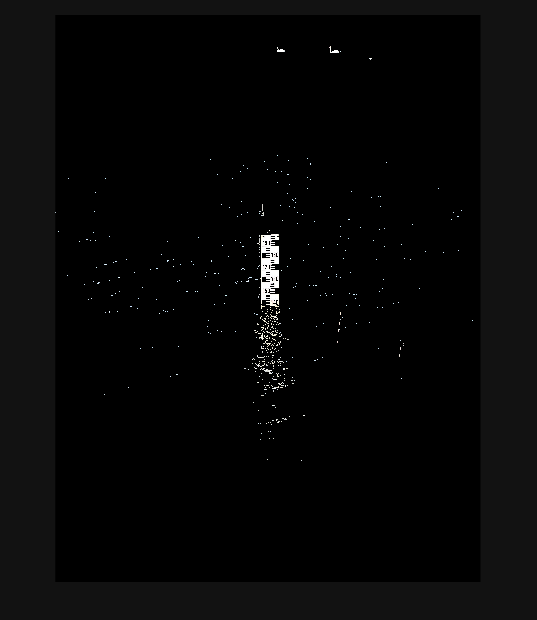

im_whites_mask = im_r > 200 & im_g >= 200 & im_b >= 200;
im_whites = im .* cast(im_whites_mask, 'like', im);
imshow(im_whites);

Solo importan los bloques grandes de blancos, así que se hace cierre

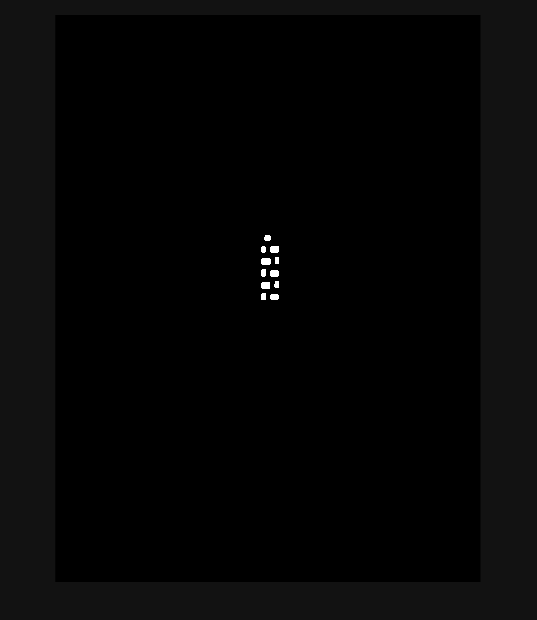

se = strel('disk',10);
im_whites_opened = imopen(im_whites_mask, se);
imshow(im_whites_opened);

Ahora solo se quiere tener todo como un bloque, para aplicar un filtro

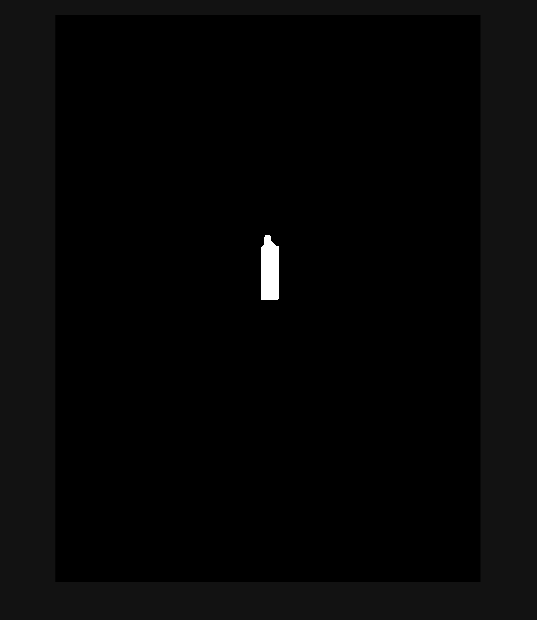

se = strel('disk',50);
im_mask_im = imclose(im_whites_opened, se);
imshow(im_mask_im);

Lo que se busca ahora es tener un rectángulo alrededo del área de interés

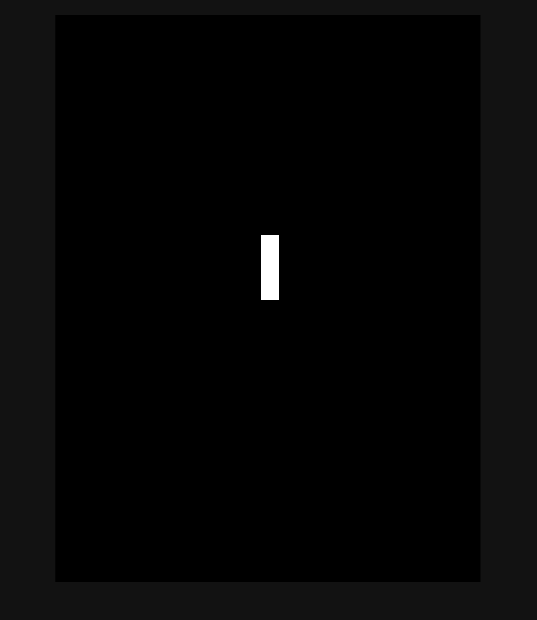

im_size = size(im_mask_im);

[rowIndices, colIndices] = find(im_mask_im);
left = min(colIndices);
right = max(colIndices);
up = min(rowIndices);
down = max(rowIndices);

im_mask_im(up:down, left:right) = 1;
imshow(im_mask_im);

Se aplica esta máscara sobre la imagen original

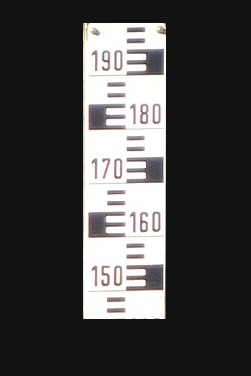

im_masked = im(up:down, left:right, :);
imshow(im_masked);

Funciona, detecta solo la regla linmimétrica

Se realiza umbralización para tener una imagen binaria

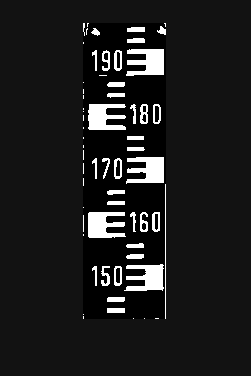

rl_binary = ~(im2gray(im_masked) > 200);
imshow(rl_binary);

Lo que se puede hacer aquí es encontrar el tamaño del período de las franjas (una blanca y una negra) por columna, de ello, se sabrá que la mediana en centímetros equivale a 4 cm. Dividir la altura entre píxles

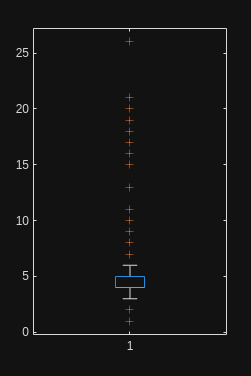

whites = [];
blacks = [];

rl_binary_size = size(rl_binary);

for col=round(rl_binary_size(2)/4) : round(rl_binary_size(2)*3/4)

    prev = rl_binary(1, col);

    distance_black = 0;
    distance_white = 0;

    distance_black_f = false;
    distance_white_f = false;

    for row=1:(rl_binary_size(1))
        
        current = rl_binary(row, col);
        if (xor(prev, current))
            if (current) % == white
                % Guardar blacks
                if (distance_black_f)
                    blacks = [blacks, distance_black];
                end
                distance_black_f = false;                
                
                distance_white = 0;
                distance_white_f = true;

            else % == black
                % Guardar whites
                if (distance_white_f)
                    whites = [whites, distance_white];
                end
                distance_white_f = false;

                distance_black = 0;
                distance_black_f = true;
            end
        end

        if (distance_white_f)
            distance_white = distance_white + 1;
        elseif (distance_black_f)
            distance_black = distance_black + 1;
        end 

        prev = current;
    end
end

boxplot(whites);

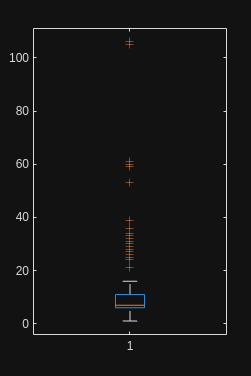

boxplot(blacks);


whites_median = median(whites)

whites_median = 4

blacks_median = median(blacks)

blacks_median = 7


period = whites_median + blacks_median;

% Imprimir la altura del río

altura_del_agua = (200 - (rl_binary_size(1) / period * 2)) / 100;
fprintf("La altura del agua es %f metros.\n", altura_del_agua)

La altura del agua es 1.461818 metros.
